# Segmenting Honeycomb Cells

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

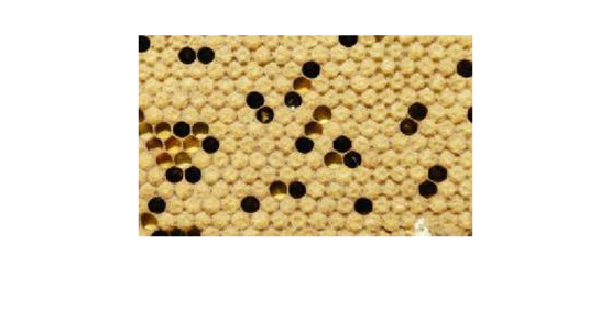

hc = imread("./images/honeycomb.jpg");
imshow(hc)

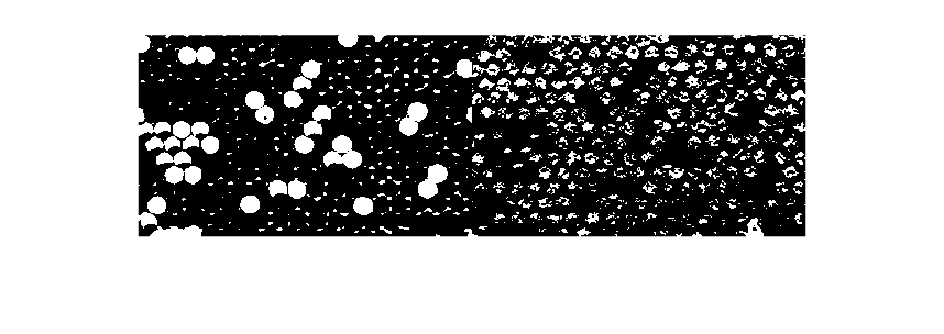


hcGS = im2gray(hc);
uncapped = hcGS < 125;
capped = hcGS > 200;
imshowpair(uncapped, capped, "montage")

## Task 1

To get a segmentation of all the cells excluding the walls, you need to segment the capped and uncapped cells separately. An initial threshold of the two types of cells shows that the uncapped cells need less cleaning than the capped cells, which are closer in intensity to the cell walls.

An initial calculation of the percent of capped cells is at the bottom of the script.

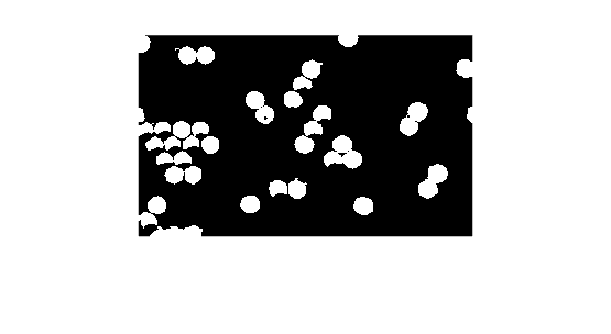

uncapped = bwareaopen(uncapped, 50);
imshow(uncapped)

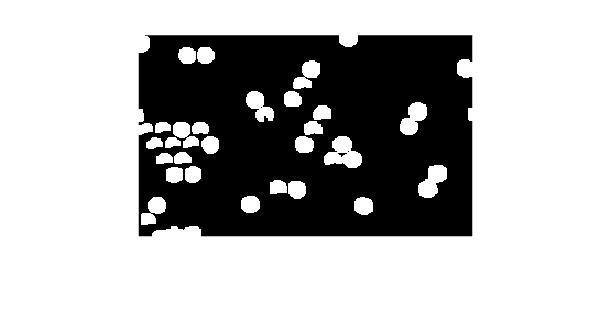


SE = strel("disk", 3);
uncapped = imopen(uncapped, SE);
imshow(uncapped)

## Task 2 & 3

A lenient threshold was used to exclude as much of the cell walls as possible from the `capped` image.  

FMM requires an initial grayscale image that approximately marks the objects that you want to segment.  There isn't a big difference in absolute intensity between the capped cells and the cell walls. But there *is* a visible change, so it's reasonable to try a gradient weight array for the grayscale image.

You can calculate a weight array of a grayscale image that is bright in areas of low change (e.g. object centers) and dark where there is a lot of change (e.g. edges) with the `gradientweight` function.

`wts` `=` `gradientweight``(``gs``)``;`

`gradientweight` creates a weight array where each weight is inversly proportional to the gradient values at that pixel location.

The edges around the uncapped cells are clearly marked because there is a large difference between the dark cells and the honeycomb walls.

You can still see different cells, but many are connected. To identify individual cells, you need to increase the sensitivity of gradient detection. 

The `"RolloffFactor"` name-value pair controls how fast the weights fall as a function of gradient. Increasing it will increase the sensitivity to the gradient.

`wts` `=` `gradientweight``(``gs``,``"RolloffFactor"``,``rof``)``;`

The default value for `"RolloffFactor"` is 3 and the recommended range is 0.5 to 4.

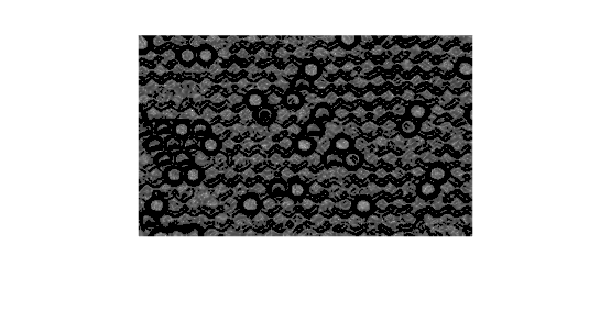

W = gradientweight(hcGS, "RolloffFactor", 3.8);
imshow(W)

## Task 4

Specifying the `"RolloffFactor"` improved the separation of the honeycomb cells, but brighter areas of foreground are still connected. 

Applying an opening operation to a grayscale image will emphasize the darker regions and break some of these connections.

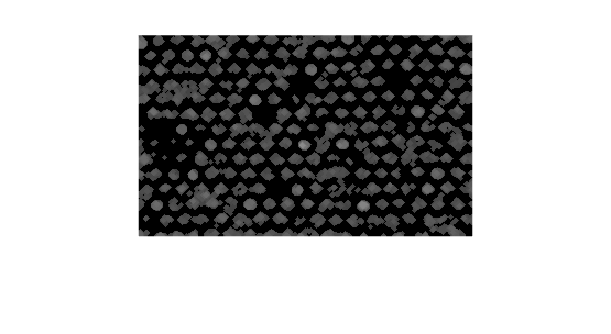

SE = strel("disk", 2);
W = imopen(W, SE);
imshow(W)

## Task 5

Now that you have a starting segmentation and a weight array that approximately identifies the honeycomb cells, you're ready to use the Fast Marching Method.

Apply the Fast Marching Method using the `imsegfmm` function.

`BW2` `=` `imsegfmm``(``wts``,``BW``,``thresh``)``;`

`wts` is the weight array, and `BW` is the starting segmentation. `thresh` is a threshold in the range [0, 1]. Low values typically result in large foreground regions (logical true) in `BW`.

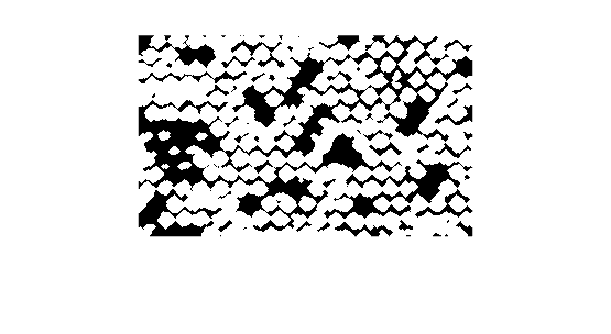

capped = imsegfmm(W, capped, .2);
imshow(capped)

This code calculates the percent of pixels identified as capped cells of the total number of pixels identified as a honeycomb cell.  (Pixels identfiying walls are excluded.)

prcntCapped = nnz(capped) / (nnz(capped) + nnz(uncapped)) *100

prcntCapped = 83.2227